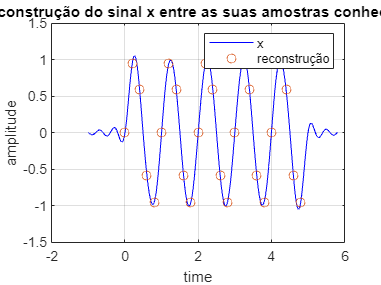

%ex 2
%a)
Ta = 0.2;
t = [0:Ta:5-Ta];
x = sin(2*pi*t);
figure(1);
ReconstroiSinal(x,Ta);

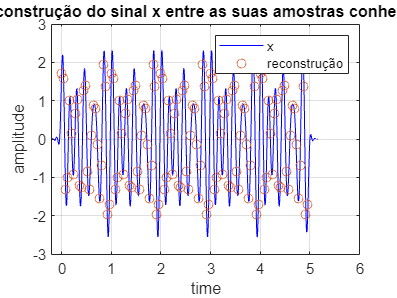


%b)
Ta = 0.04;
t = [0:Ta:5-Ta];
y = sin(10*pi*t) + cos(12*pi*t) + cos(14*pi*t - pi/4);
figure(2);
ReconstroiSinal(y,Ta);

function [y,yTa] = ReconstroiSinal(x,Ta)


% x ..... sinal a reconstruir
% Ta .... período de amostragem do sinal x
% y ..... sinal reconstruido
% yTa ... período de amostragem do sinal reconstruido (100 vezes menor que Ta)
%


% fator de "oversampling"
oversampling = 100;

% instantes de tempo das amostras de x
xT = (0:length(x)-1)*Ta;

% cálculo de yTa (período de amostragem de y)
yTa = Ta/oversampling;

% instantes de tempo das amostras de y (tempos considerando 5 amostras extras de x de cada lado)
yT = (-5*oversampling:oversampling*(length(x)+4))*yTa;

% inicialização do sinal de saída
y = zeros(1,length(yT));

% adição da contribuição de cada amostra de x no sinal y; cada amostra vem multiplicada pela funcão sinc centrada nessa amostra
for ix=1:length(x)
  y = y+x(ix)*sinc((yT-xT(ix))/Ta);
end

% mostrar resultado quando o se usam os argumentos de saída desta funçãnão
if nargout == 0
  figure; % nova figura
  plot(yT,y,'b',xT,x,'o');
  xlabel('time');
  ylabel('amplitude');
  title('Reconstrução do sinal x entre as suas amostras conhecidas');
  legend('x','reconstrução');
  zoom on;
  grid on;
end
end